Rotation Matrices

R_acino_to_cv = [1 0 0
                0 0 -1
                0 1 0]

R_acino_to_cv =      1     0     0
     0     0    -1
     0     1     0


R_cv_to_c1to = [1 0 0
                0 1 0
                0 0 1]

R_cv_to_c1to =      1     0     0
     0     1     0
     0     0     1


R_cv_to_c2to = [1 0 0
                0 1 0
                0 0 1]

R_cv_to_c2to =      1     0     0
     0     1     0
     0     0     1



alp = 0

alp = 0

bet = 0

bet = 0


R_cam1t0_to_cam1tx = [cos(alp) 0 sin(alp)
                0 1 0
                -sin(alp) 0 cos(alp)]

R_cam1t0_to_cam1tx =      1     0     0
     0     1     0
     0     0     1


R_c2t0_to_c2tx = [cos(bet) 0 sin(bet)
                0 1 0
                -sin(bet) 0 cos(bet)]

R_c2t0_to_c2tx =      1     0     0
     0     1     0
     0     0     1



R1 = R_cam1t0_to_cam1tx * R_cv_to_c1to * R_acino_to_cv

R1 =      1     0     0
     0     0    -1
     0     1     0


R2 = R_c2t0_to_c2tx * R_cv_to_c2to * R_acino_to_cv

R2 =      1     0     0
     0     0    -1
     0     1     0


Translation Vectors

C1 = [0
      0
      0]

C1 =      0
     0
     0


C2 = [1
      0
      0]

C2 =      1
     0
     0



t1 = -R1 * C1

t1 =      0
     0
     0


t2 = -R2 * C2

t2 =     -1
     0
     0



R1t1 = [R1 t1]

R1t1 =      1     0     0     0
     0     0    -1     0
     0     1     0     0


R2t2 = [R2 t2]

R2t2 =      1     0     0    -1
     0     0    -1     0
     0     1     0     0


Plot Axes

plot3([0 1], [0 0], [0, 0], "LineWidth", 2, "Color", "red")
hold on
plot3([0 0], [0 1], [0, 0], "LineWidth", 2, "Color", "red")
hold on
plot3([0 0], [0 0], [0, 1], "LineWidth", 2, "Color", "red")

text(0,0,0, 'WCF Origin')
xlabel('X') 
ylabel('Y')
zlabel('Z')

xlim([-1 5])
ylim([-1 5])
zlim([-2 5])
grid on

plot3([0 0.5], [0 0], [0, 0], "LineWidth", 1, "Color", "blue")
hold on
plot3([0 0], [0 0.5], [0, 0], "LineWidth", 1, "Color", "blue")
hold on
plot3([0 0], [0 0], [0, -0.5], "LineWidth", 1, "Color", "blue")
text(0,0,-0.5, 'C1 Origin')

plot3([1 1.5], [0 0], [0, 0], "LineWidth", 1, "Color", "blue")
hold on
plot3([1 1], [0 0.5], [0, 0], "LineWidth", 1, "Color", "blue")
hold on
plot3([1 1], [0 0], [0, -0.5], "LineWidth", 1, "Color", "blue")
text(1,0,0, 'C2 Origin')

Plot Points

P1w = [1
       1
       1
       1]

P1w =      1
     1
     1
     1


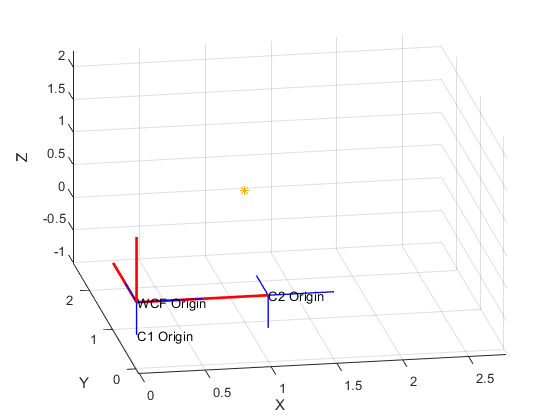


plot3(P1w(1), P1w(2), P1w(3), "Marker","*")


P1c1 = R1t1 * P1w

P1c1 =      1
    -1
     1


P1c2 = R2t2 * P1w

P1c2 =      0
    -1
     1
